% 读取数据
clc,clear;
warning('off')
T1 = readtable('2018年国赛A题附件.xlsx','Sheet',1);
T2 = readtable('2018年国赛A题附件.xlsx','Sheet',2);
ClothInfo = table2array(T1(:,2:end));
insTemp = table2array(T2(:,2));
ClothInfo(2,4) = 6;
ClothInfo(4,4) = 5;
ClothInfo(:,4) = ClothInfo(:,4) * 1e-3;

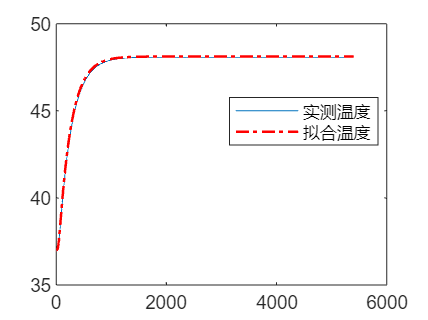

% 隐式解法参数设定
dx = [0.00001,0.00005,0.00005,0.00005];      % 空间间隔
dt = 1;     % 时间间隔

% 粗略搜索
% 因为h1不敏感，h2敏感，所以对h1进行枚举，对h2进行三分
minLoss = inf;
bestH = [];
lb = [100, 8];
ub = [130, 9];
tol = 1e-2;     % 容差

for h1 = lb(1):0.5:ub(1)
    hl = lb(2);      % 区间左端点
    hr = ub(2);      % 区间右端点
    while abs(hr-hl) > tol
        mid1 = hl + (hr - hl) / 3;
        mid2 = hr - (hr - hl) / 3;
        if ImpTempLoss([h1, mid1],dx,dt,ClothInfo,insTemp) < ImpTempLoss([h1, mid2],dx,dt,ClothInfo,insTemp)
            hr = mid2;
        else
            hl = mid1;
        end
    end
curLoss = ImpTempLoss([h1, (hl + hr) / 2],dx,dt,ClothInfo,insTemp);

if curLoss < minLoss
    minLoss = curLoss;
    bestH = [h1, (hl + hr) / 2];
    fprintf("找到更小损失值：%f，更新H为：[%f, %f]\n", minLoss, h1, (hl + hr) / 2);
end

end

找到更小损失值：0.004171，更新H为：[100.000000, 8.295702]
找到更小损失值：0.003881，更新H为：[100.500000, 8.298818]
找到更小损失值：0.003604，更新H为：[101.000000, 8.298818]
找到更小损失值：0.003338，更新H为：[101.500000, 8.301708]
找到更小损失值：0.003085，更新H为：[102.000000, 8.305562]
找到更小损失值：0.002845，更新H为：[102.500000, 8.305321]
找到更小损失值：0.002615，更新H为：[103.000000, 8.308211]
找到更小损失值：0.002397，更新H为：[103.500000, 8.312065]
找到更小损失值：0.002190，更新H为：[104.000000, 8.313450]
找到更小损失值：0.001998，更新H为：[104.500000, 8.313450]
找到更小损失值：0.001811，更新H为：[105.000000, 8.316340]
找到更小损失值：0.001636，更新H为：[105.500000, 8.320194]
找到更小损失值：0.001473，更新H为：[106.000000, 8.319953]
找到更小损失值：0.001318，更新H为：[106.500000, 8.322843]
找到更小损失值：0.001174，更新H为：[107.000000, 8.326697]
找到更小损失值：0.001039，更新H为：[107.500000, 8.326697]
找到更小损失值：0.000913，更新H为：[108.000000, 8.328623]
找到更小损失值：0.000796，更新H为：[108.500000, 8.331032]
找到更小损失值：0.000689，更新H为：[109.000000, 8.333708]
找到更小损失值：0.000590，更新H为：[109.500000, 8.335635]
找到更小损失值：0.000500，更新H为：[110.000000, 8.338043]
找到更小损失值：0.000418，更新H为：[110.500000, 8.339970]
找到更小损失值：0.

% 精细搜索
% 因为h1不敏感，h2敏感，所以对h1进行枚举，对h2进行三分
minLoss = inf;
bestH = [];
lb = [115.8, 8];
ub = [116.0, 9];
tol = 1e-5;     % 容差
failStep = 5;   % 累计5步无更优解就停止
curStep = 0; 
for h1 = lb(1):0.01:ub(1)
    hl = lb(2);      % 区间左端点
    hr = ub(2);      % 区间右端点
    while abs(hr-hl) > tol
        mid1 = hl + (hr - hl) / 3;
        mid2 = hr - (hr - hl) / 3;
        if ImpTempLoss([h1, mid1],dx,dt,ClothInfo,insTemp) < ImpTempLoss([h1, mid2],dx,dt,ClothInfo,insTemp)
            hr = mid2;
        else
            hl = mid1;
        end
    end
curLoss = ImpTempLoss([h1, (hl + hr) / 2],dx,dt,ClothInfo,insTemp);
curStep = curStep + 1;
if curLoss < minLoss
    curStep = 0;
    minLoss = curLoss;
    bestH = [h1, (hl + hr) / 2];
    fprintf("找到更小损失值：%e，更新H为：[%f, %f]\n", minLoss, h1, (hl + hr) / 2);
end
if curStep > 5 
    break;
end

end

找到更小损失值：1.230492e-05，更新H为：[115.800000, 8.358257]
找到更小损失值：1.227482e-05，更新H为：[115.810000, 8.358292]
找到更小损失值：1.224727e-05，更新H为：[115.820000, 8.358328]
找到更小损失值：1.222226e-05，更新H为：[115.830000, 8.358363]
找到更小损失值：1.219979e-05，更新H为：[115.840000, 8.358395]
找到更小损失值：1.217987e-05，更新H为：[115.850000, 8.358431]
找到更小损失值：1.216249e-05，更新H为：[115.860000, 8.358465]
找到更小损失值：1.214765e-05，更新H为：[115.870000, 8.358499]
找到更小损失值：1.213534e-05，更新H为：[115.880000, 8.358534]
找到更小损失值：1.212558e-05，更新H为：[115.890000, 8.358568]
找到更小损失值：1.211835e-05，更新H为：[115.900000, 8.358604]
找到更小损失值：1.211366e-05，更新H为：[115.910000, 8.358637]
找到更小损失值：1.211150e-05，更新H为：[115.920000, 8.358673]


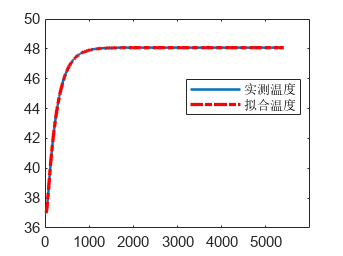

% 函数测试
close all;
h = [115.92,8.35867];
[loss,uu] = ImpTempLoss(h,dx,dt,ClothInfo,insTemp);
figure();
plot(insTemp,'LineWidth',1.5); hold on
plot(uu(end,:), 'LineWidth',1.2,'Color','r','LineStyle','-.','LineWidth',2)
legend("实测温度","拟合温度",'Location','best');

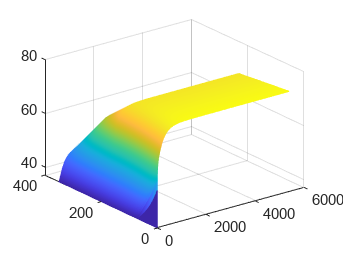


figure();
mesh(uu);